# Lesson 4

Written by Brenda So and Cory Nezin

# Objective

After this class, you should be able to:

- Know how to use control sequences (for, if, else, while, try and catch block)

- Understand how to plot graphs

- Start out on the homework

# Control Sequences

Similar to C, MATALB has control sequence commands. Last class we explored for loops and the difference between for loops and vectorization. Even though vectorization is more computationally efficient than loops, sometimes for loops, and other control sequences, are necessary, such as to perform simulations. However, assuming that everyone has an understanding of control sequences, I would not delve too deep into the discussion of the mechanics of if and while statements, but rather, I would show you the semantics of the statmeents. 

# For Loops

total=0;
for i=1:10
    total = total + i;
end
total

total = 55

# If...Else Statements

vgpa = 1.76;
wgpa = 2.52;
xgpa = 3.55;
ygpa = 3.76;
zgpa = 3.83;
gpa = xgpa;
if gpa < 2
    fprintf('You are in DANGER!!!\n')
elseif gpa >= 2 && gpa < 3.5
    fprintf('You are safe.\n')
elseif gpa >= 3.5 && gpa < 3.7
    fprintf('Cum Laude\n')
elseif gpa >= 3.7 && gpa < 3.8
    fprintf('Magna Cum Laude\n')
elseif gpa >= 3.8 && gpa < 4
    fprintf('Summa Cum Laude\n')
end

Cum Laude


# While Loop

total=0;
i=0;
while i<=10
    total = total + i;
    i = i+1;
end
total

total = 55

# Try and catch blocks

Try and catch blocks are particularly useful if you don't know whether a certain statement would occur and the new code depends on that certain line of code. Try and catch allows you to "catch" errors and display error statements

try
    a = [1 2; 3 4];
    b = [1 2 3 4];
    c = a*b
catch err
    fprintf('You are trying to do something which is not allowed');
    % you can check documation for more things you you can do and
    % information you can get from the error
end

You are trying to do something which is not allowed

# Plotting

We are going to go through several plotting schemes, and explore how you can customize plotting. We would go through 2D plotting, surface plotting, subplot, stem plot and 3D plotting

# Plotting in 2D

2D plots are very straightforward, it's what you expect from a textbook or when you are graphing.

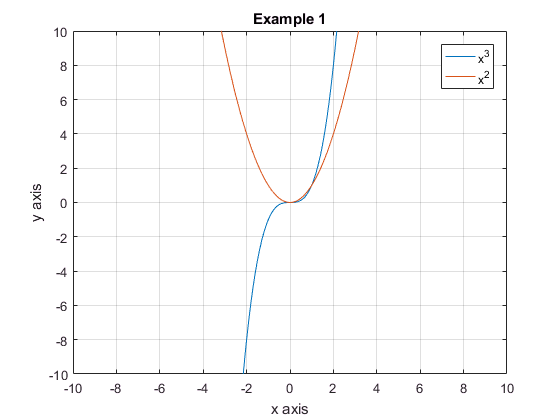

% Example 1: Plotting y=x^3

x = -10:0.1:10;
y = x.^3;
plot(x,y,'DisplayName','x^3');              % plotting line graph
xlabel('x axis');
ylabel('y axis');
title('Example 1');
grid on;
axis([-10 10 -10 10]);

hold on;                % plotting more than 1 plot on 1 figure rather than overwriting

y2 = x.^2;
plot(x, y2, 'DisplayName','x^2');
legend('show');

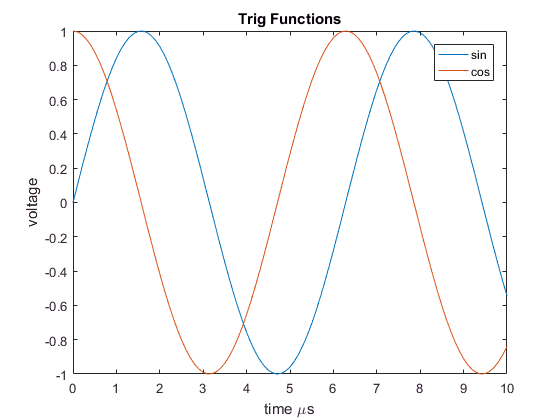

% Example 2: Plotting sine and cosine

t = 0:.1:10;
d1 = sin(t);
d2 = cos(t);

figure 
plot(t,[d1.' d2.']) % plot(t,d1,t,d2)

title('Trig Functions')
xlabel('time \mus') % \mus is a special symbol. Other examples include: \beta, \pi, \leq, \infty 
ylabel('voltage')
legend('sin','cos')

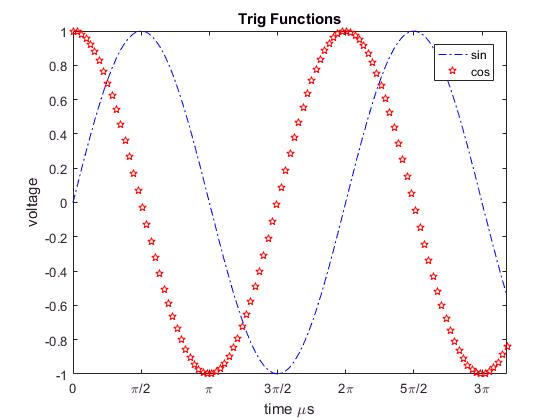

% Here we are going to get a bit fancy and change up some stuff. 
figure;

plot(t,d1,'b-.',t,d2,'rp') % We are changing up the line pattern and color
title('Trig Functions')
xlabel('time \mus') % \mus is a special symbol. Other examples include: \beta, \pi, \leq, \infty 
ylabel('voltage')
legend('sin','cos')
xticks(0:pi/2:10)
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi', '5\pi/2','3\pi'})

# SubPlots

Subplots exist for stylistic purposes. Let's say you have a signal and you want to plot the magnitude and phase of the signal itself. It would make more sense if the magnitude and phase plots exist in the same figure. There are several examples fo subplot below to explain how it works. Note that linear indexing of plots is different from normal linear indexing. 

figure;
subplot(2,2,1)
plot(t,d1)
hold on;
plot(t,d2)
title('Normal plot')

subplot(2,2,2)
plot(t,d1,'b-.',t,d2,'rp')
title('Customized plot')

%% Stem plots
% stem plots are particularly useful when you are representing digital
% signals, hence it is good to learn them too!
subplot(2,2,[3 4])
stem(t,d1)
hold on;
stem(t,d2)
title('Stem plots')

# 3D and surface plots

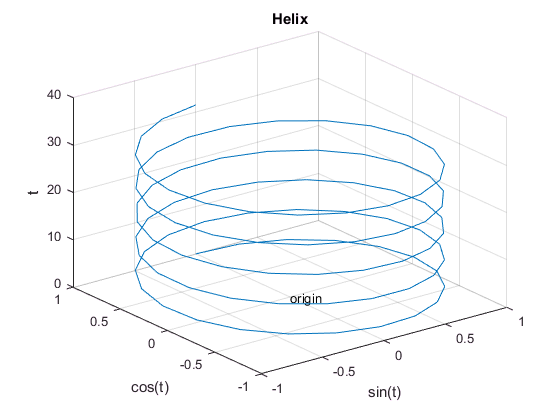

%% 3D and surface plots

% 3D plotting: The helix
t = linspace(0,10*pi);
figure;
plot3(sin(t),cos(t),t)
xlabel('sin(t)'),ylabel('cos(t)'),zlabel('t')
text(0,0,0,'origin')
grid on;
title('Helix')

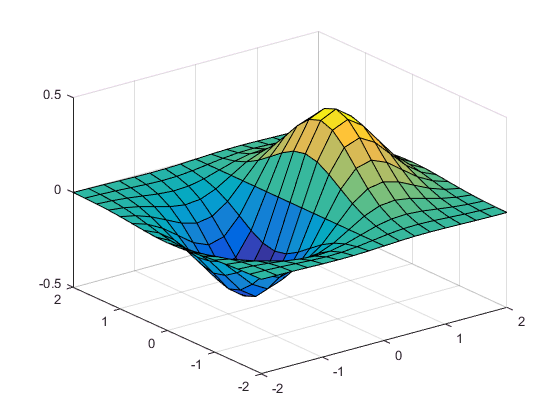


% Surface plot: This is an example taken from lesson 2, so hopefully this
% is going to ring some bells
a1 = -2:0.25:2;
b1 = a1;
[A1,B1] = meshgrid(a1);
% Here we plot the surface of f(x) = x*exp^(x.^2+y.^2)
F = A1.*exp(-A1.^2-B1.^2);
figure;
surf(A1,B1,F)

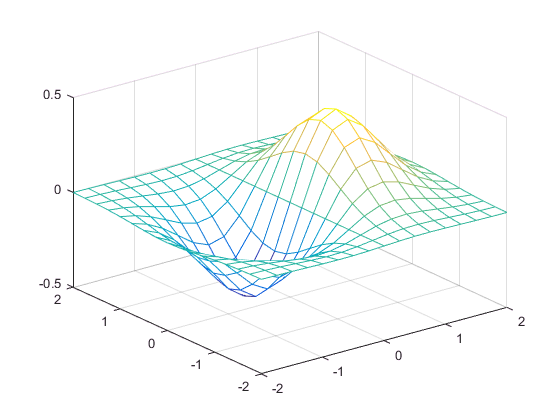

figure;
mesh(A1,B1,F)

# Lab

Write a function that takes in an N x 1 vector of standard deviations, $\sigma$, an M x 1 vector of means, $\mu$, and an P x 1 vector of evaluation points.  The function should then plot NxM Gaussian shapes characterized by $F_{i,j} \left(x\right)=\text{ }\frac{1}{\sqrt{2\pi {\sigma^2 }_{ˆi} }}\times exp\left(−\frac{{\left(x−u_j \right)}^2 }{2{\sigma_i }^2 }\right)$. (where i ranges from 1 to N and j ranges from 1 to M)  Basically, plot the equation for every combination of $\mu$and $\sigma$.  Add appropriate legends and and axis labels.

- First, generate the Gaussian vectors.  This can be done without any loops using ndgrid.

- Create a new figure.  Enumerate through all of the $\mu 's$and $\sigma 's$ using a double for loop.

- Within the loop, Create a legend which identifies each curve by its standard deviation and mean.  For example if you want to add a label for a curve with standard deviation 3 and mean 2, write 

        legendString =    ['\mu = ',num2str(2),' \sigma = ',num2str(3)];

             and

        plot(x,yourCurveNameGoesHere,'DisplayName',legendString) 

            Make sure you hold on!

        4.  Finally, Give it a title, add some labels, and show the legend.

Here is an example of what your final product should look like:

%gaussPlot(linspace(0,5,1000), [1 2 3], [0.1 0.2 0.3] ) %gaussPlot(x,mu,sigma)